# TrialFinder

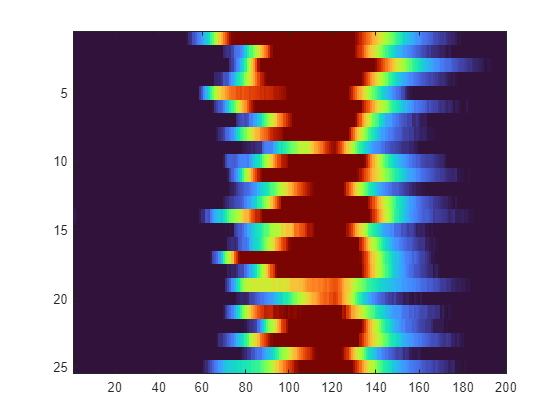

structName = [path, 'responseSum.mat'];
if isfile(structName)
    load(structName)
else
    responseSum = struct;
end

stimOptions = {'vibration','brush','heat','cold', 'estim'};
[i_stim,~] = listdlg('PromptString',{'Select the stimulus used.'},...
    'SelectionMode','single','ListString',stimOptions );
stim = stimOptions{i_stim};
badtrial = 1;
if strcmp(stim,'vibration')
    normDeltaF_byTrial = reshape(normDeltaF,[200, size(normDeltaF,1)/200, size(normDeltaF,2)]);
    maxTrial = zeros(size(normDeltaF,2),1);
    for i = 1:size(normDeltaF,2)
        maxResponse = max(normDeltaF_byTrial(:,:,i));
        maxResponse(badtrial) = 0;
        [~,maxTrial(i)] = max(maxResponse);
    end

    badROI = [];
    [responseROI, ~] = setdiff(responseROI0, badROI);
    dataToPlot = zeros(200, numel(maxTrial));
    for i = 1:size(normDeltaF,2)
        dataToPlot(:,i) = normDeltaF_byTrial(:,maxTrial(i),i);
    end

    figure, imagesc(dataToPlot(:,responseROI)')
    colormap('turbo');
    caxis([0.05, 1])
    responseSum.responseROI = responseROI;
    responseSum.(stim) = dataToPlot(:,responseROI);
    pathparts = strsplit(path,filesep);
    index = find(contains(pathparts,'analysis'));
    % structpath = extractBefore(path,pathparts(index+2));
    % structName = [structpath, 'responseSum.mat'];
    mouseID = string(pathparts(index+2));
    responseSum.mouseID = mouseID;
else
    try
        responseSum.(stim) = normDeltaF(:,responseSum.responseROI);
        disp(['the response to ', stim, ' has been added'])
    catch ME
        warning('please set and save the responseROI of vibration first')
        rethrow(ME)
    end
end


save(structName,"responseSum");

sumFolder = 'E:\Dropbox (HMS)\LQCalciumImaging1\analysis\TrkBCreER';
sumName = fullfile(sumFolder, 'summary.mat');
summary = struct;
filelist = dir(fullfile(sumFolder, '**\responseSum.mat'));

for i= 1:numel(filelist)
    path = filelist(i).folder;
    if contains(path,'male') && ~contains(path,'female')
        gender = 'male';
    elseif contains(path, 'female')
        gender = 'female';
    end
    if ~isfield(summary, gender)
        summary.(gender) = struct;
    end
    pathparts = strsplit(path,filesep);
    pathID = string([pathparts{end-1},'_',pathparts{end}]);
    load(fullfile(path, "responseSum.mat"))
    fields = fieldnames(responseSum);
    for j = 1:numel(fields)
        if isfield(summary.(gender),fields{j})
            summary.(gender).(fields{j}) = [summary.(gender).(fields{j}), responseSum.(fields{j})];
        else
            summary.(gender).(fields{j}) = responseSum.(fields{j});
        end
    end
end

vibration = summary.male.vibration(:,1:end-1);
responseStart = zeros(size(vibration,2),1);
for i = 1:size(vibration, 2)
    signal = vibration(:,i) - 7*std(vibration(1:40,i)) - mean(vibration(1:40,i));
    temp = find(signal>0);
    responseStart(i) = temp(1);
end
[~, index] = sort(responseStart);

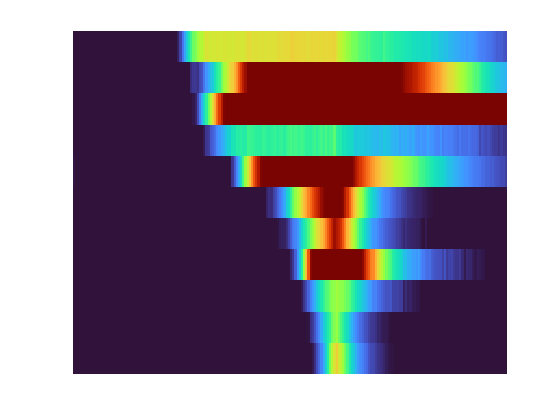

figure, imagesc(vibration(:,index)');
set(gcf,'Visible','on')
set(gca, 'OuterPosition', [0,0,1,1])
colormap('turbo');
caxis([0.05, 1])
axis off
box off

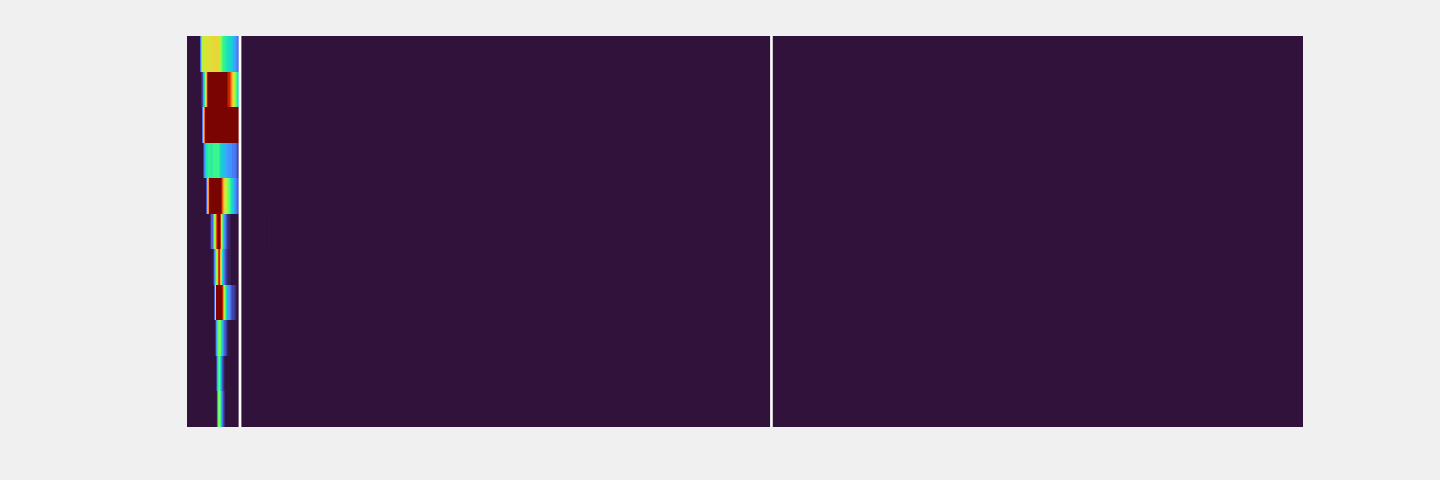

allResponse = [vibration(:, index); summary.male.heat(:,index);summary.male.cold(:,index)];
f = figure('units','inch',"Position", [1, 1, 15, 5]);
set(gcf,'Visible','on')
set(gca, 'OuterPosition', [0,0,1,1])
imagesc(allResponse')
colormap('turbo');
caxis([0.05, 1])
axis off
box off
hold on
line([200, 200],[0 size(allResponse, 2)+0.5],'color','white', 'Linewidth', 2)
line([2200, 2200], [0 size(allResponse, 2)+0.5], 'color', 'white', 'Linewidth', 2)

vibration = summary.female.vibration;
responseStart = zeros(size(vibration,2),1);
for i = 1:size(vibration, 2)
    signal = vibration(:,i) - 7*std(vibration(1:40,i)) - mean(vibration(1:40,i));
    temp = find(signal>0);
    responseStart(i) = temp(1);
end
[~, index] = sort(responseStart);

estim = summary.female.estim;
[~,index] = sort(max(estim(100:350,:)), 'descend');

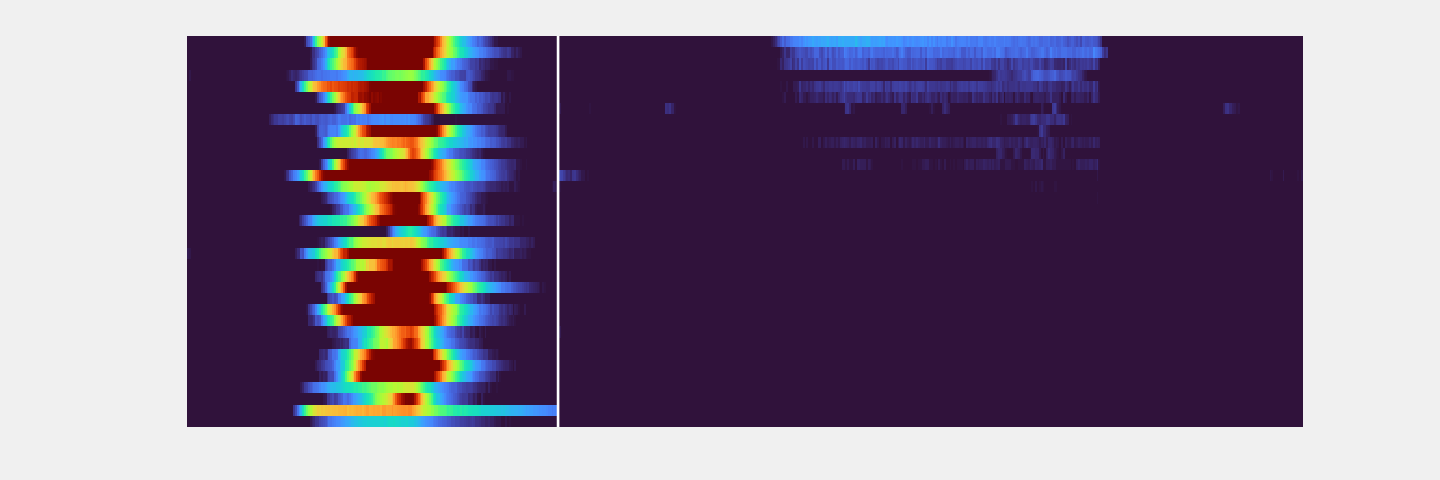


allResponse = [vibration(:, index); summary.female.estim(:,index)];
f = figure('units','inch',"Position", [1, 1, 15, 5]);
set(gcf,'Visible','on')
set(gca, 'OuterPosition', [0,0,1,1])
imagesc(allResponse')
colormap('turbo');
caxis([0.05, 1]);
axis off
box off
hold on
line([200, 200],[0 size(allResponse, 2)+0.5],'color','white', 'Linewidth', 2);

% line([2200, 2200], [0 size(allResponse, 2)+0.5], 'color', 'white', 'Linewidth', 2)